## Import Data

clear all;
clc;
data = readtable("step_osc_150ohm_voltage_divider_2.csv");
data = fillmissing(data,'nearest');
data([1,2],:) = [];

## Assign Variables

% Seperate values
t = table2array(data(:,1))+20;
ADC = round(table2array(data(:,3))/5*1024);
OCR = table2array(data(:,2));

% Match to duty cycle
OCR = round(OCR/5)*10+65;

% Find index before step
idx = find(OCR<75,1,'last')

idx =     22.0000e+000



% Trim data with new index
t = t(idx-9:end);
ADC = ADC(idx-9:end);
OCR = OCR(idx-9:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s =     15.6200e-003


## Plot Real Data

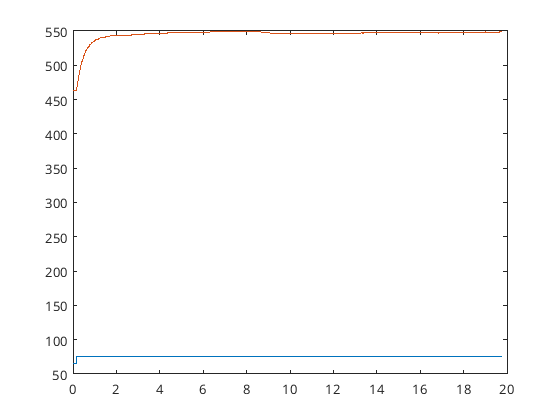

clf;
plot(t,OCR)
hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

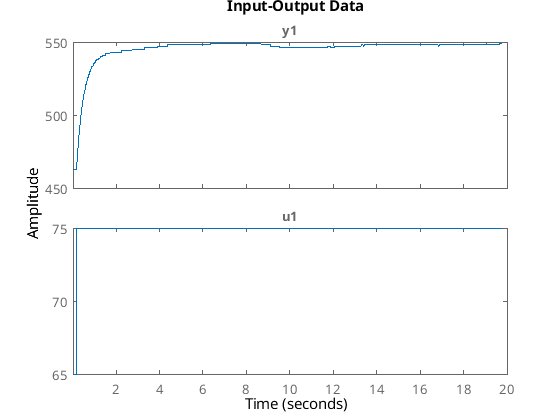

idd = iddata(ADC,OCR,T_s);
plot(idd)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
          475.2
  ---------------------
  s^2 + 26.83 s + 65.12
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 86.76%                  
FPE: 2.188, MSE: 2.171                          


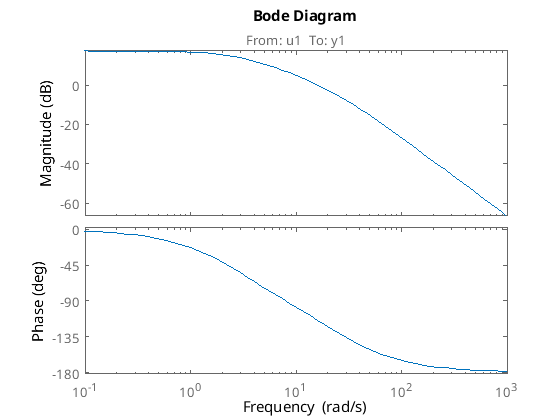

bode(G)

dcgain(G)

ans =      7.2977e+000


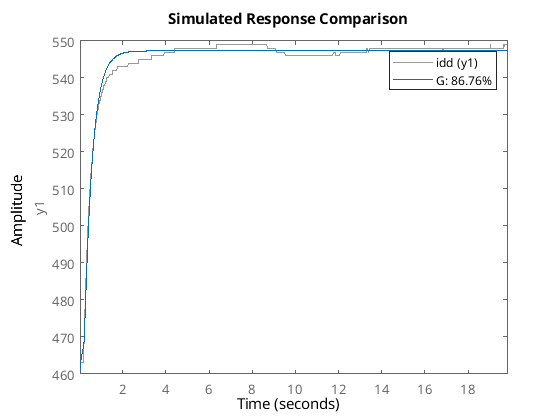

compare(idd,G)  % Passer meget godt med dataet

## Create PID Controller

abs(pole(G))

ans =     24.1339e+000
     2.6981e+000


gm = 177; Ni=3; alpha=1.5;
[wc, Kp, ok] = findp(G,gm);

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

s=tf('s');
Cpid=Kp %*(taui*s+1)/(taui*s);%*(taud*s+1)/(alpha*taud*s+1);

Cpid =    137.1827e-003


%Cpid = minreal(Cpid)
Gol=minreal(G*Cpid)

Gol =
 
  From input to output "y1":
          65.19
  ---------------------
  s^2 + 26.83 s + 65.12
 
Continuous-time transfer function.



Gcl=minreal(Gol/(1+Gol))

Gcl =
 
  From input "y1" to output "y1":
          65.19
  ---------------------
  s^2 + 26.83 s + 130.3
 
Continuous-time transfer function.



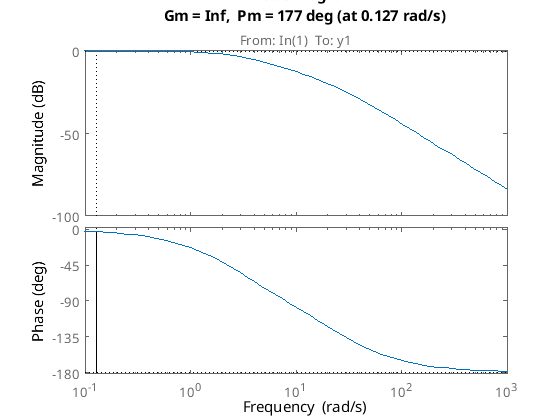

margin(Gol);

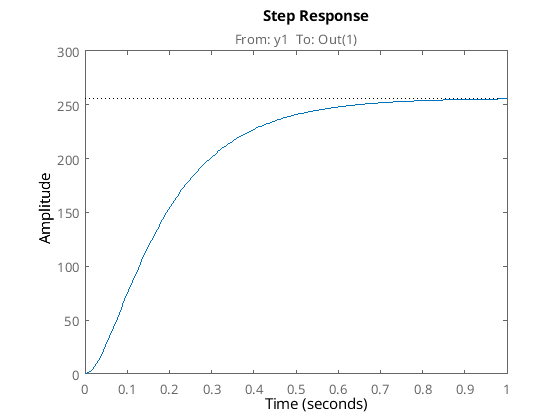

step(512*Gcl);

## Z-Transform

Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable='z^-1'

Gz =
 
  0.2192 - 0.2192 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



[num, den] = tfdata(Gz, 'v')

num =    219.2245e-003  -219.1982e-003


den =      1.0000e+000    -1.0000e+000


%stepz([num],[den]);

## Discrete Implementation

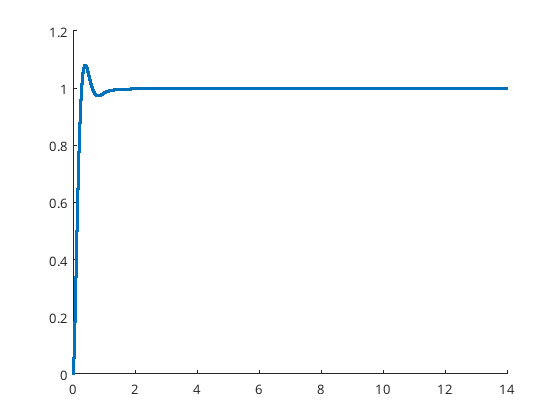

% Build time vector
dt=1/10e3;
t = 0:dt:14;

% Build step input
u = ones(size(t));
u(1:5)=0;

% Initialize values
y = zeros(size(t));

% Step through time and solve the difference equation
for i = 5:length(t)
        uvals = num(1)*u(i)+num(2)*u(i-1)+num(3)*u(i-2)+num(4)*u(i-3)+num(5)*u(i-4);
        yvals = -den(2)*y(i-1)-den(3)*y(i-2)-den(4)*y(i-3)-den(5)*y(i-4);
        y(i) = uvals + yvals;
end

scatter(t,y,3)